# Using the DSS block to Simulate a Finite Element Model

Copyright 2021 The MathWorks, Inc.

This project will demonstrate a workflow for simulating a finite element model inside of a control loop in Simulink. The project contains:

- A top level model, and its referenced subsystem files

- data: a directory containing physical component data that is needed for modeling

- figures: data visualization and example manufacturer data for digitization

- models: Simulink model and subsystem files

- src: scripts for defining modeling parameters, generating FE matrices, and a model order reduction function

This example uses a model generated using MATLAB's PDE Toolbox, however this workflow aims to capitalize the structure of the finite element formulation so that it can be plugged into the Descriptor State Space block in Simulink. A model order reduction (MOR) technique is applied to the finite element model before simulation to reduce the degrees of freedom to be computed, in turn speeding up the simulations.

## System Overview

The system being modeled in this Simulink example is a variable-speed fan cooling a CPU which, depending on the model and the operating point, can generate variable amount of heat. Each component of the system is modeled using empirical data and technical specifications, and assumptions are stated in the following discussion regarding levels of modeling fidelity.

Opening the model, we can take a look at the control loop, which is described in the next section.

mdl = 'top_system';
open_system(mdl)

## Control Loop Components

### Plant: CPU & Heat Sink

The plant in this system is the thermal dynamics of the heat-generating CPU and the heat-dissipating heat sink. These dynamics are modeled by a finite element formulation of the heat equation on the 3D geometry. The geometry, meshing, and discretization in this example are done using MATLAB’s PDE Toolbox. The finite element matrices generated can then be solved using Simulink’s Descriptor State Space block. For more information on time-dependent finite-element formulations, please see the MathWorks documentation. [4] The dominant mode of heat transfer in this scenario is due to convection and is governed by the equation:


$$\dot{q} =h\left(T_{\infty } -T\right)$$


The coefficient h is the convective heat transfer coefficient and can be found experimentally and varies as a function of mass flow rate. Again, for simplicity values are interpolated linearly between a free convection coefficient (no airflow) to a maximum forced convection coefficient. Like the fan performance plots, empirically derived values can be used to construct a lookup table for a mass flow dependent coefficient value. A convective boundary condition was constructed for the ducted airflow where forced convection coefficients would be applied on the internal fin surfaces that see airflow, and free convection coefficients were applied on the external facing surfaces of the system.

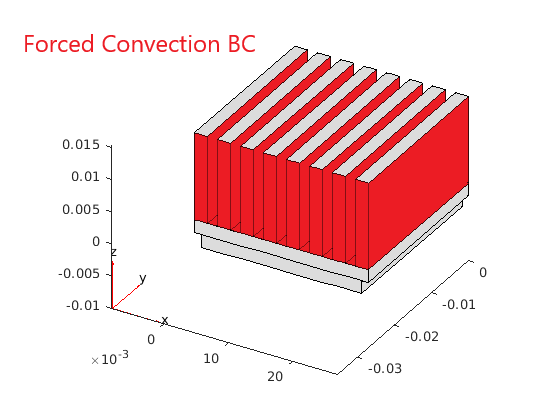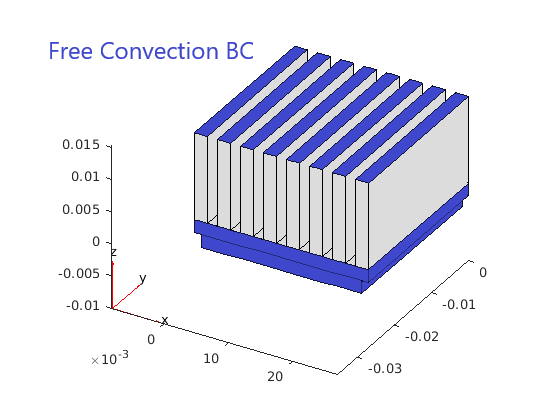

The heat generation of the CPU can be controlled by the user in this formulation as an input Wattage. This demonstration provides examples of different loadings of the processor that lead to different heat generation, thus lending itself useful for design decisions in determining if a certain heat sink is suitable for a specific CPU.

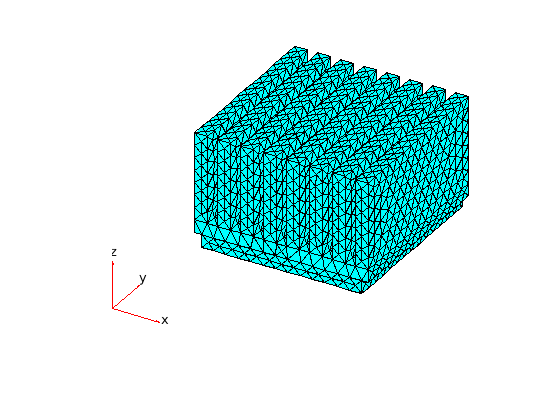

%heat_sink_defs_DEBUG
heat_sink_defs
pdeplot3D(heatsink)

### Actuation

The performance of the cooling fan used in this model is approximated using numbers in the typical range of consumer grade fans. The two values of interest for the fan are the RPM output from an input voltage and the corresponding volumetric flow rate at that RPM. For simplicity in this example, maximum values are provided for RPM and CFM and intermediate values are linearly interpolated depending on the voltage and RPM input, respectively. Fan performance plots can be obtained from manufacturers and these can be digitized into a data table using a plot digitization tool. [1] Using this plot digitization to lookup table technique, the model can better capture nonlinearities by adding more data points. In order to get mass flow rate, the International Standard Atmosphere model was used at sea level elevation to get an air density of 1.2250 kg/m^3 . This data is available from the Aerospace Toolbox. [2] Finally, inertial effects need to be introduced to the fan model to account for the delay from voltage input to RPM output. To do this, a Simscape simulation was run by adapting the “Thermistor-Controlled Fan” example. [3] The DC motor with a rotational inertia of 1E-5 kg·m 2 attached to it was run at 12V and the time to reach 63.2% of the steady state rotational velocity was computed and used as a first-order time constant. Future simulation considerations can make use of noise data available for cooling fans. Additional requirements for noise levels can be added to test whether or not a specific fan model is capable of adequately cooling a CPU while staying sufficiently quiet for customer requirements.

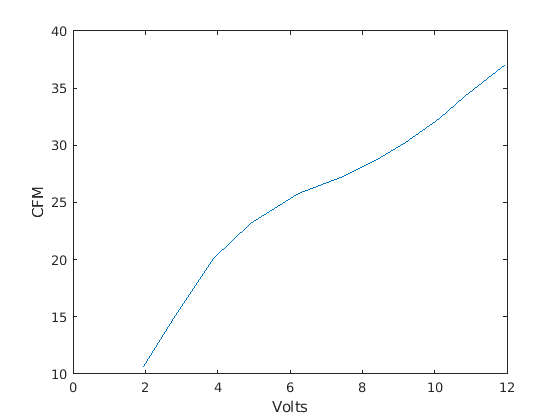

fan_defs
plot(V2CFM(:,1),V2CFM(:,2)); xlabel("Volts"); ylabel("CFM")

### Sensor

The sensor temperature dynamics, like the fan inertial effects, are model by a first order time constant. For this example, chip-level thermal behaviour is typically on the order of one second, so a value of 1 second is used. The time constant is specific to each sensor depending on the type of sensor and the application, but this information will be provided by the manufacturer of the sensor. The value may also be a function of another variable, in which case the plot digitization workflow can be employed again. As discussed in the next section, the compensation is based on case tempereature, so this is where the sensor will be located (this was computed in the plant section previously) and shown as a red dot in figure.

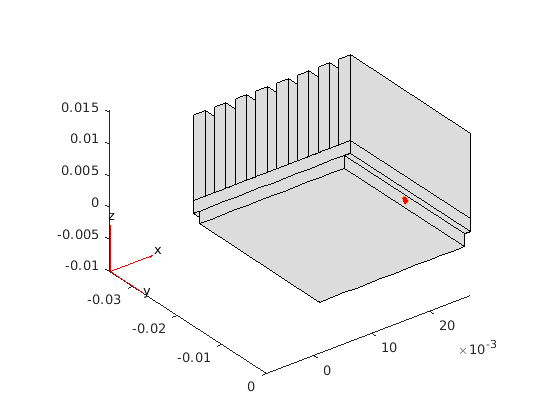

sensor_defs
pdegplot(heatsink)
view([37.5 -30])
hold on
scatter3(m.Nodes(1,outID),m.Nodes(2,outID),...
         m.Nodes(3,outID),'MarkerFaceColor',[1 0 0])

### Compensation

A PID controller is used to enforce a temperature limit of 70.0°C on the processor case. Temperature limits are typically provided by the manufacturer and can be easily integrated into this model. In this example, the sensing location is on the case, so the limit used is for the case, however the sensor can be placed on the die and the limit accordingly set to the maximum junction temperature. To avoid overheating, the temperature limit set-point for the controller is specified as 60.0°C. The cooling fan used by this model is driven by a 12V electric motor. Thus, the controller output is saturated to a lower limit of 0V, indicating the motor is not running and there is no forced convective cooling, and an upper limit of 12V, which corresponds to the highest speed of the motor and therefore the highest convective heat transfer the system is capable of.

## Model Order Reduction

This example using a finite element formulation of the heat equation on the heat sink is quite computationally intensive, requiring matrix equations of size 18,559 x 18,559. This method therefore naturally presents an opportunity to apply a model order reduction technique in order to reduce the resources needed to simulate. An option to choose between the full-order finite element model or a reduced-order version of the FE model was added in the "Choose fidelity" block in the CPU + Heat Sink subsystem. The user now has an option to choose the size of the reduced model such that the the execution time of running a simulation goes from approximately one day down to less than one minute.

A model order reduction app with a GUI has been provided in this project. The app and the Simulink models in this project save and load ROMs and their corresponding source models into MAT-files. The next section of code will create these files if they do not already exist.

% define full fidelity DSS model
sys.A = (Q+K); % multiply by -1 in DSS block
sys.B = speye(nDoF,nDoF);
sys.C = speye(nDoF,nDoF);
sys.D = sparse(nDoF,nDoF);
sys.E = M;
if (~isfile([topdir filesep 'data' filesep 'baseline.mat']))
    save([topdir filesep 'data' filesep 'baseline.mat'],'sys');
end
% reduce model and save
if (~isfile([topdir filesep 'data' filesep 'ROM.mat']))
    rsys = modalTruncation(sys,[0 50]);
    rsys0 = rsys;
    save([topdir filesep 'data' filesep 'ROM.mat'],'rsys');
    save([topdir filesep 'data' filesep 'ROM0.mat'],'rsys0');
end

To launch the app, simply execute the command below. There are a handful of user-tunable parameters that can be used to optimize the size of the reduced system for a target error tolerance. Th first action the user will want to take is to check the validity of the ROM for the source model; that is, check whether there have been chagnes to the source since generating the ROM. To generate a new ROM, the user will need to identify an acceptable allowable error compared to the source model. The frequency range range of interest determines the bounds for the modes to be retained after modal truncation. Choosing this range requires prior knowledge about the system of interest from the user. The remaining two parameters are the number of modes retained, corresponding to the size of the reduced system. The figures below are the results of testing modal truncation on the heat sink and CPU model, and they provide insights into the computational cost benefits from MOR as well as the tradeoffs it has with numerical accuracy. The app will generate the error plot and the user can then determine the optimal size of the ROM and sav it to file.

Note, generating error analysis plot may take a long time. It is recommended to keep the stored MAT-file errorAnalysisResults.mat once it is saved.

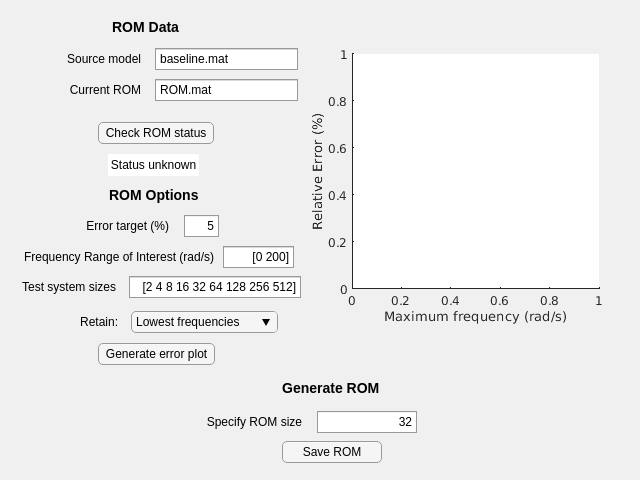

ROMapp;

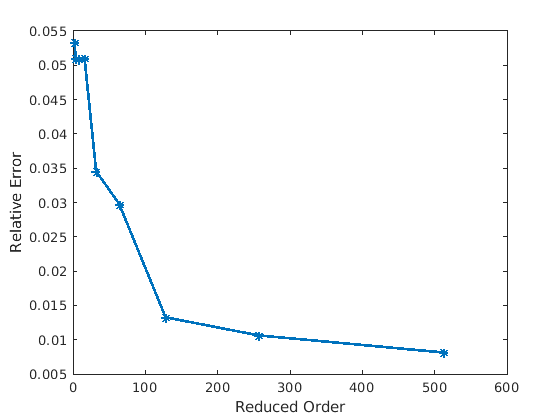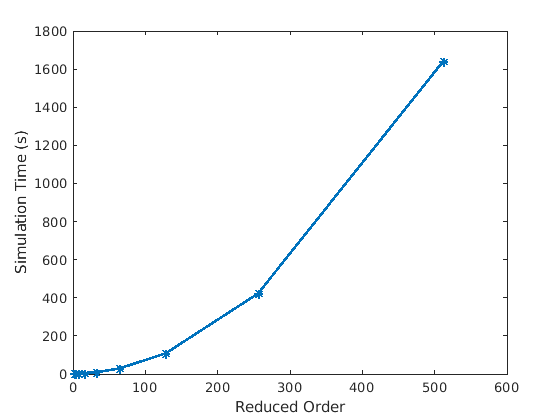

The method provided to the user is a projective technique that uses modal truncation, which is described by the equations below. It is left to the user to study the provided technique by consulting the code included in the ROMapp, and to implement their own MOR techniques if the performance of modal truncation is deemed insufficient for the application of interest.


$$A_r =V^T \textrm{AV}$$



$$B_r =\;\;V^T B\;$$



$$C_r =\;\;\;\textrm{CV}\;\;$$



$$D_r =\;\;\;\;\;D\;\;\;$$



$$E_r =V^T \textrm{EV}$$


## Running the Model

[01-Jun-2022 13:10:54] Checking for availability of parallel pool...
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).
[01-Jun-2022 13:12:16] Starting Simulink on parallel workers...
[01-Jun-2022 13:12:17] Loading project on parallel workers...
[01-Jun-2022 13:12:17] Configuring simulation cache folder on parallel workers...


[01-Jun-2022 13:12:26] Loading model on parallel workers...
[01-Jun-2022 13:13:01] Transferring base workspace variables used in the model to parallel workers...
[01-Jun-2022 13:13:03] Running simulations...
[01-Jun-2022 13:13:22] Completed 1 of 100 simulation runs
[01-Jun-2022 13:13:22] Completed 2 of 100 simulation runs
[01-Jun-2022 13:13:22] Completed 3 of 100 simulation runs
[01-Jun-2022 13:13:23] Completed 4 of 100 simulation runs
[01-Jun-2022 13:13:23] Completed 5 of 100 simulation runs
[01-Jun-2022 13:13:23] Completed 6 of 100 simulation runs
[01-Jun-2022 13:13:28] Completed 7 of 100 simulation runs
[01-Jun-2022 13:13:29] Completed 8 of 100 simulation runs
[01-Jun-2022 13:13:29] Completed 9 of 100 simulation runs
[01-Jun-2022 13:13:29] Completed 10 of 100 simulation runs
[01-Jun-2022 13:13:29] Completed 11 of 100 simulation runs
[01-Jun-2022 13:13:30] Completed 12 of 100 simulation runs
[01-Jun-2022 13:13:35] Completed 13 of 100 simulation runs
[01-Jun-2022 13:13:35] Completed 1

nSims = 100;
in(1:nSims) = Simulink.SimulationInput(mdl);
for i = 1:nSims
    in(i) = setBlockParameter(in(i),[mdl '/Heat Generation'], ...
                                'ActiveScenario', ['Scenario' num2str(i)]);
end
out = parsim(in,'TransferBaseWorkspaceVariables','on');

openSimulationManager(in,out)

## References

[1] The MathWorks, Inc., GRABIT (https://www.mathworks.com/matlabcentral/fileexchange/7173-grabit), MATLAB Central File Exchange.

[2] The MathWorks, Inc., "Use International Standard Atmosphere model," [Online]. Available: https://www.mathworks.com/help/aerotbx/ug/atmosisa.html.

[3] The MathWorks, Inc., "Thermistor-Controlled Fan," [Online]. Available: https://www.mathworks.com/help/physmod/sps/ug/thermistor-controlled-fan.html.

[4] The MathWorks, Inc, "Finite Element Method Basics," [Online]. Available: https://www.mathworks.com/help/pde/ug/basics-of-the-finite-element-method.html.